clc
clear all

fs = 48000

fs = 48000

load("interpolated_mat_files\DOA_interpolated.mat")
load("interpolated_mat_files\P_interpolated.mat")

size_signal = length(DOA_interpolated)

size_signal = 361

DOA_inter{1,1} = DOA_interpolated;
P_inter{1,1} = P_interpolated(1:size_signal);

% original datapoint
load("rt40_mat_files\DOA_rt40.mat")
load("rt40_mat_files\pressure_rt40.mat")

DOA_first{1,1} = DOA{1,1};
P_first{1,1} = P{1,1};
DOA_original{1,1} = DOA{2,1};
P_original{1,1} = P{2,1};
DOA_third{1,1} = DOA{3,1};
P_third{1,1} = P{3,1};

clear DOA_interpolated
clear P_interpolated

clear DOA
clear P

a = createSDMStruct('DefaultArray','GRASVI50','fs',fs,'winLen',15);

User-defined SDM Settings are used :
           fs: 48000
            c: 345
       winLen: 15
    parFrames: 8192
    showArray: 0
      micLocs: [6×3 double]



v = createVisualizationStruct('DefaultRoom','LargeRoom',...
    'name','ESAT STADIUS Lab','fs',fs,'t',[2 5 10 20 50 100 200 2000]);

createVisualizationStruct : User-defined visualization settings are used :
              fs: 48000
           plane: 'lateral'
             DOI: 'forward'
       plotStyle: 'line'
            name: 'ESAT STADIUS Lab'
             res: 1
               t: [2 5 10 20 50 100 200 2000]
          colors: [8×3 double]
       dBSpacing: 6
      DOASpacing: 30
      dBDynamics: 45
       linewidth: [1 1 1 1 1 1 1 1]
        showGrid: 1
    smoothMethod: 'average'
       smoothRes: 3



Started visualization of parameters.


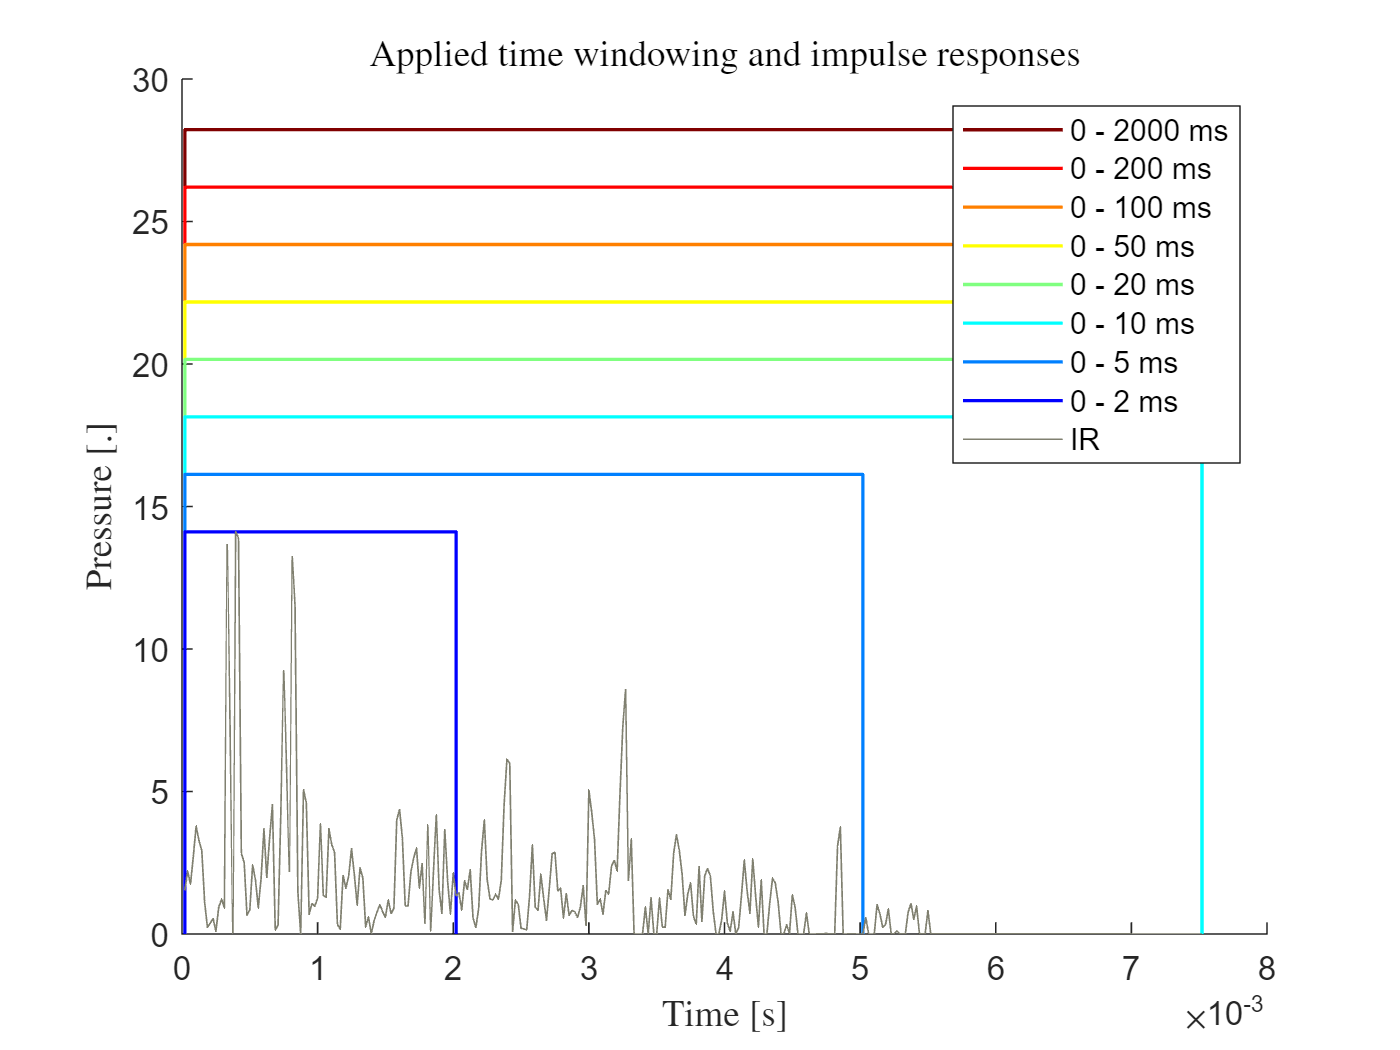

Ended visualization of parameters in 2.3914 seconds.


% For visualization purposes, set the text interpreter to latex
set(0,'DefaultTextInterpreter','latex')
parameterVisualization(P_inter, v);

Started visualization of parameters.


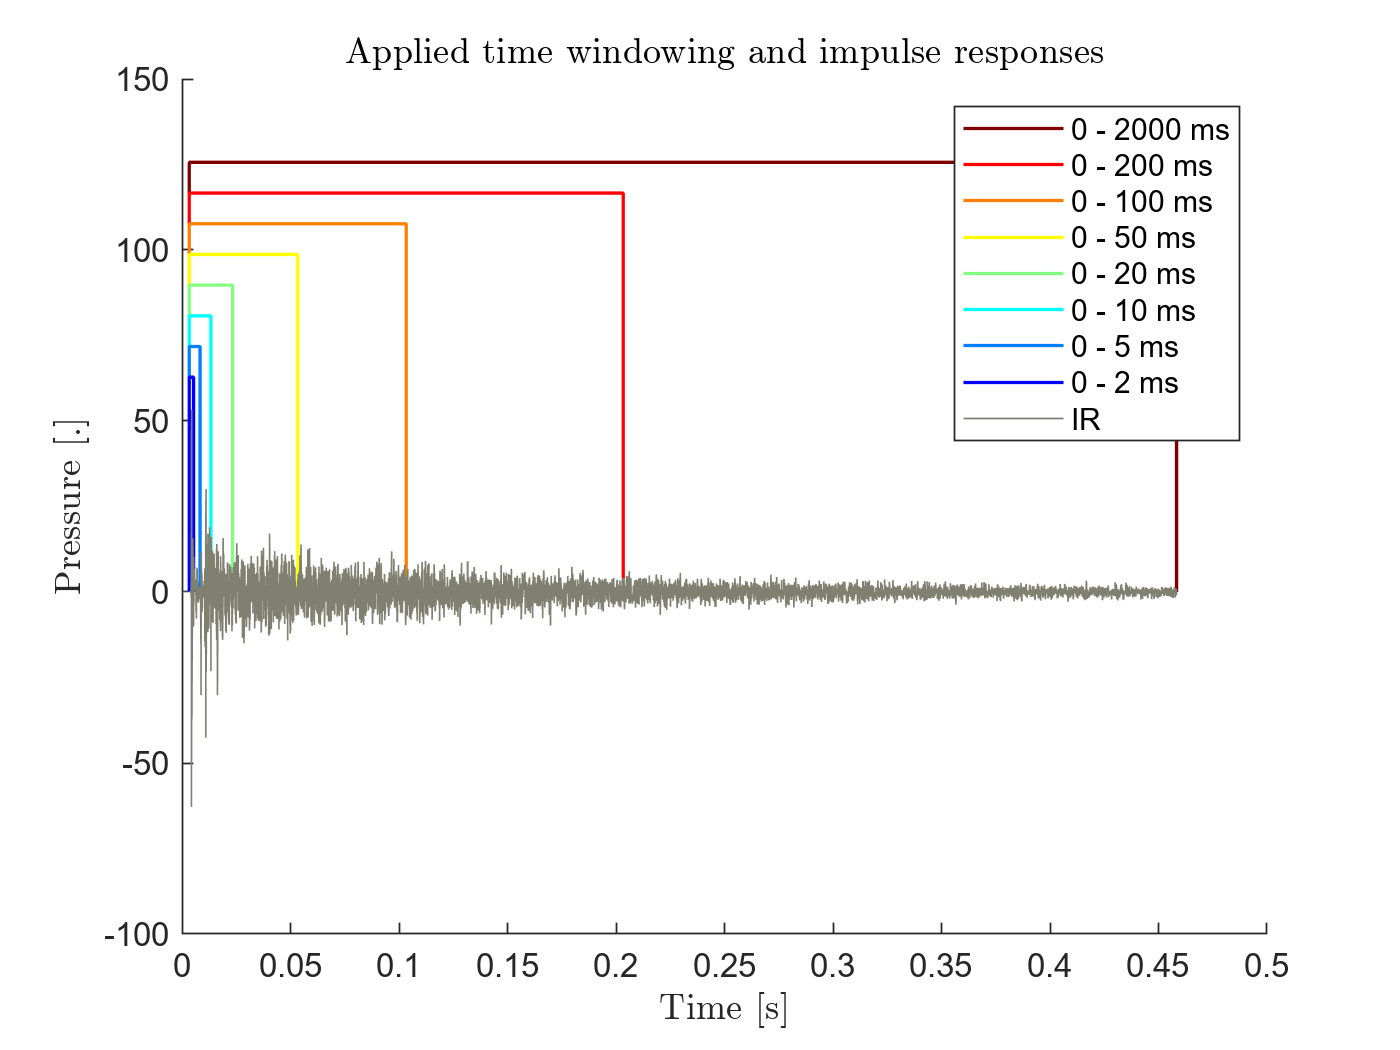

Ended visualization of parameters in 0.23328 seconds.


parameterVisualization(P_original, v);

Started time-frequency visualization.


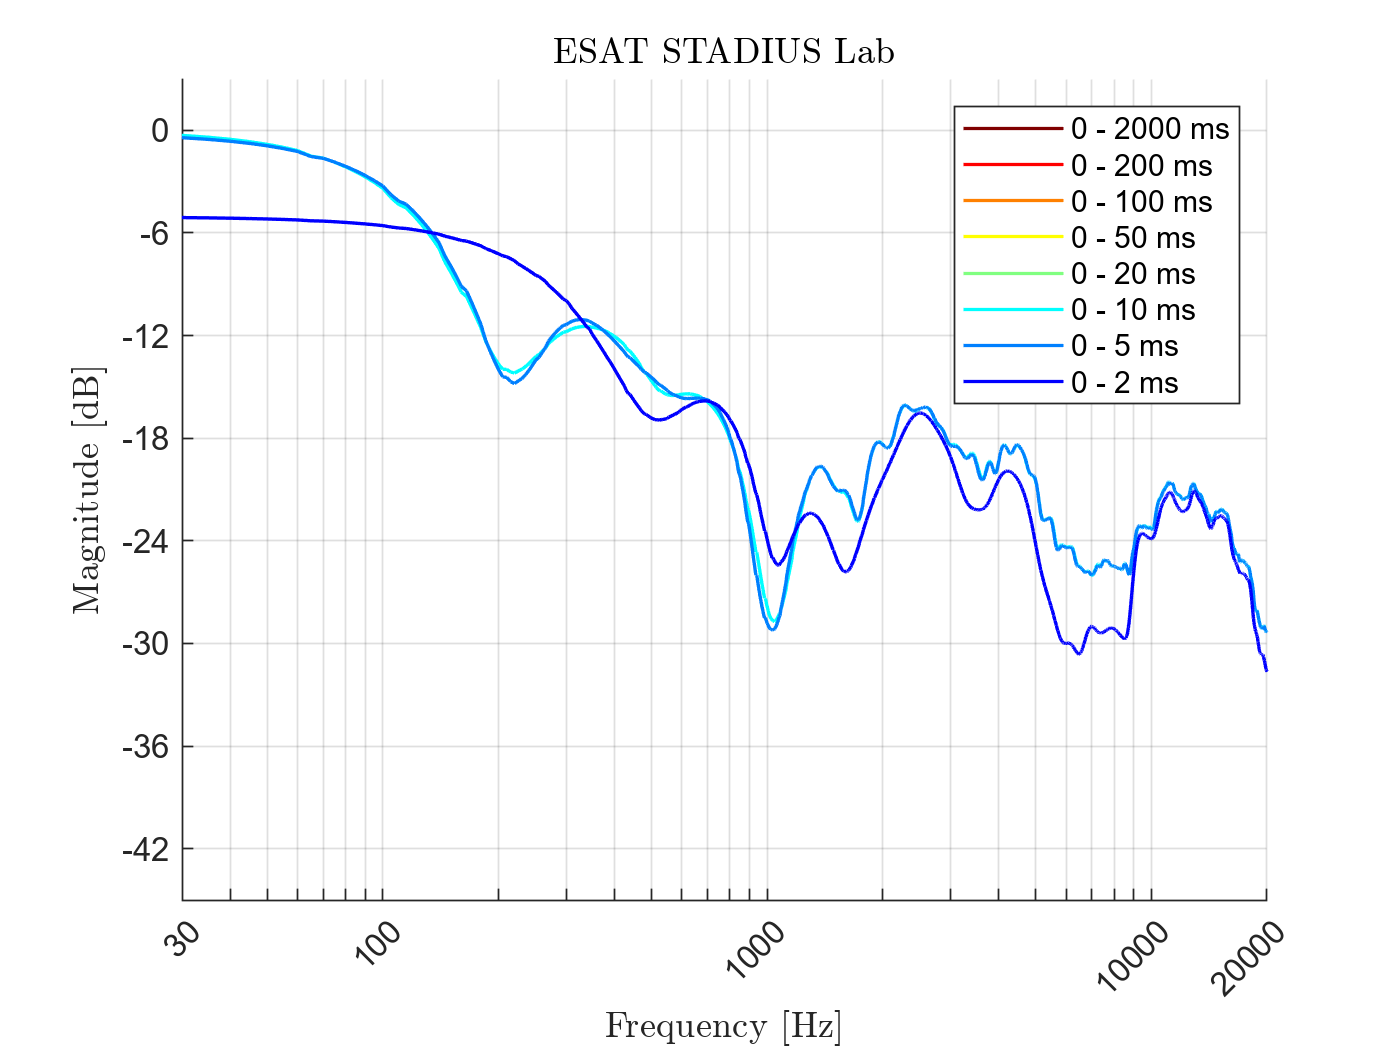

Ended time-frequency visualization in 0.82343 seconds.


timeFrequencyVisualization(P_inter, v);

Started time-frequency visualization.


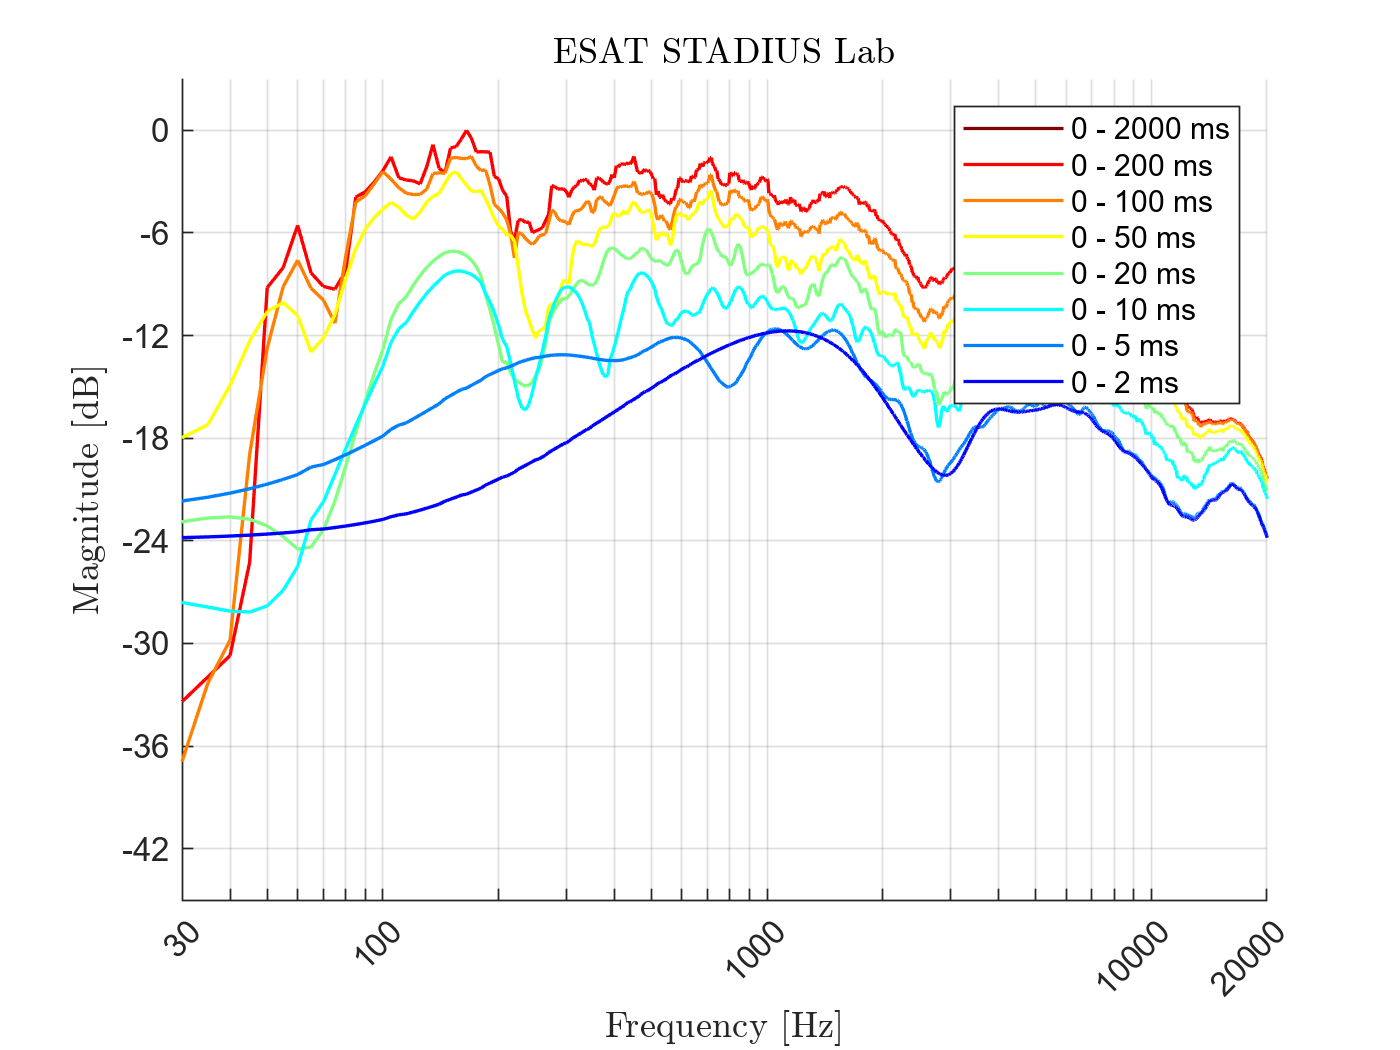

Ended time-frequency visualization in 0.45553 seconds.


timeFrequencyVisualization(P_original, v);

Started spatio-temporal visualization.


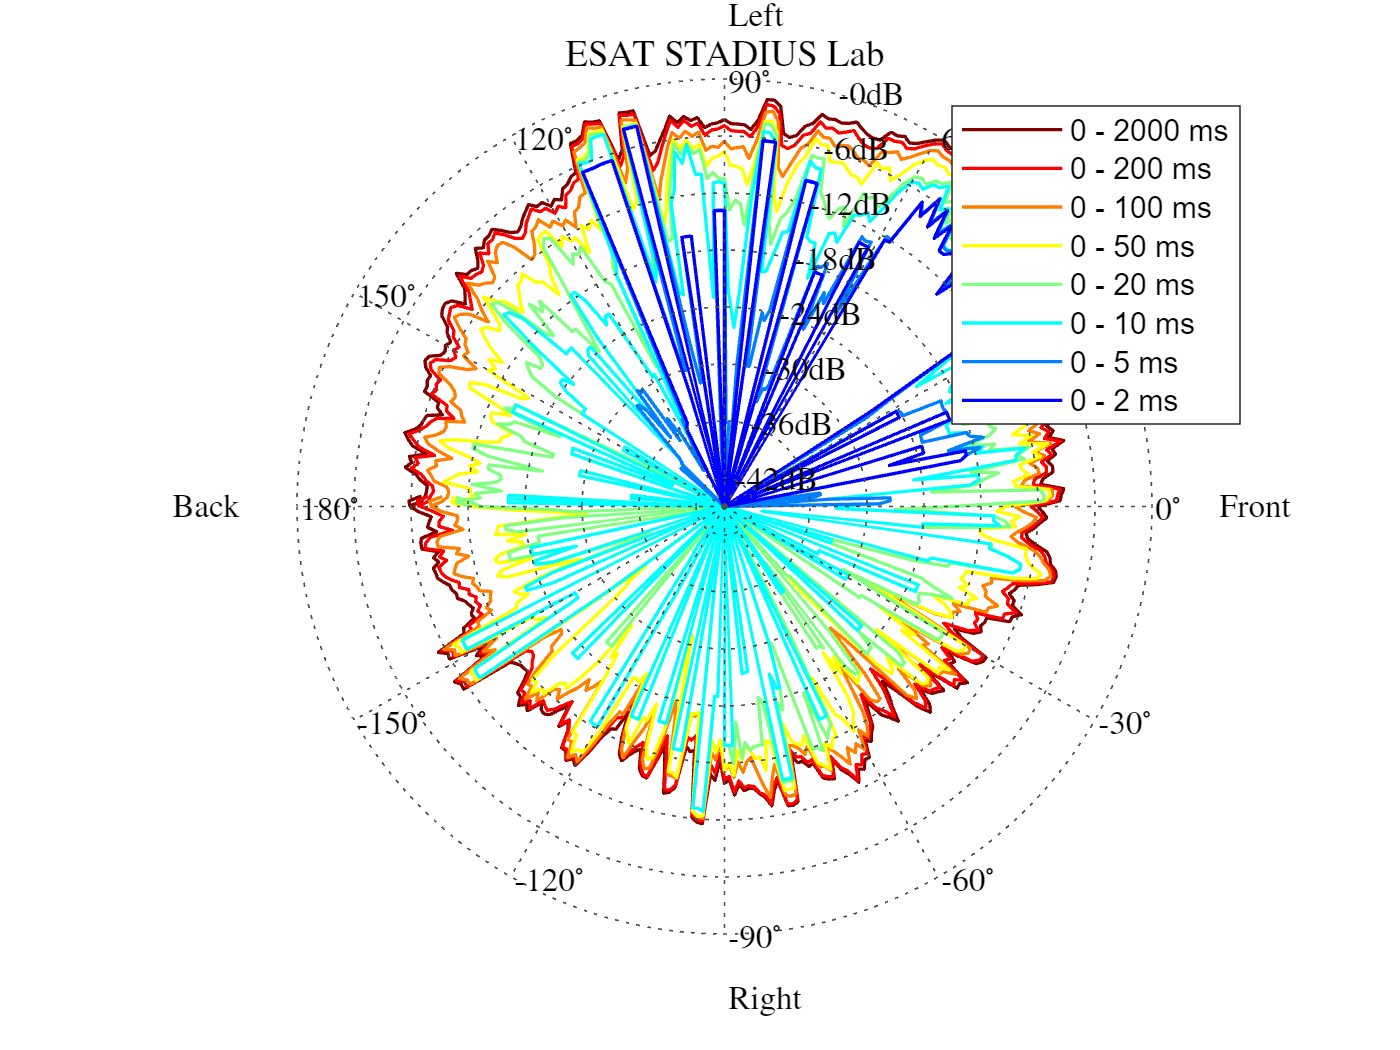

Ended spatio-temporal visualization in 0.57942 seconds.


ans = -106

v.plane = 'lateral';
% First measurement
spatioTemporalVisualization(P_first, DOA_first, v)

Started spatio-temporal visualization.


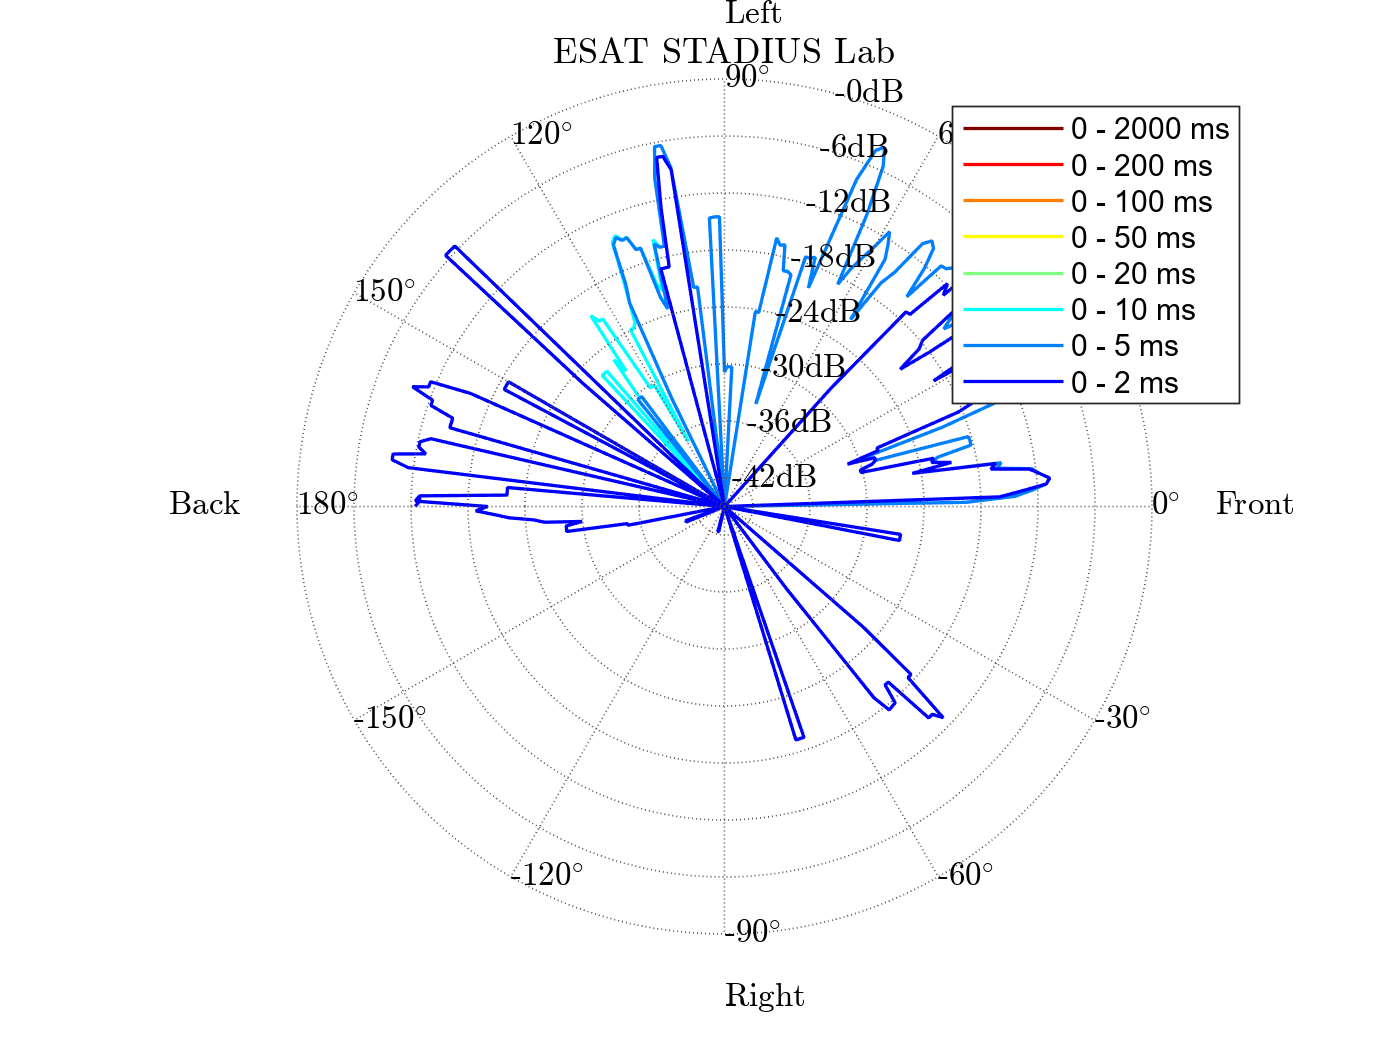

Ended spatio-temporal visualization in 0.25325 seconds.


ans = -29

% Interpolated
spatioTemporalVisualization(P_inter, DOA_inter, v)

Started spatio-temporal visualization.


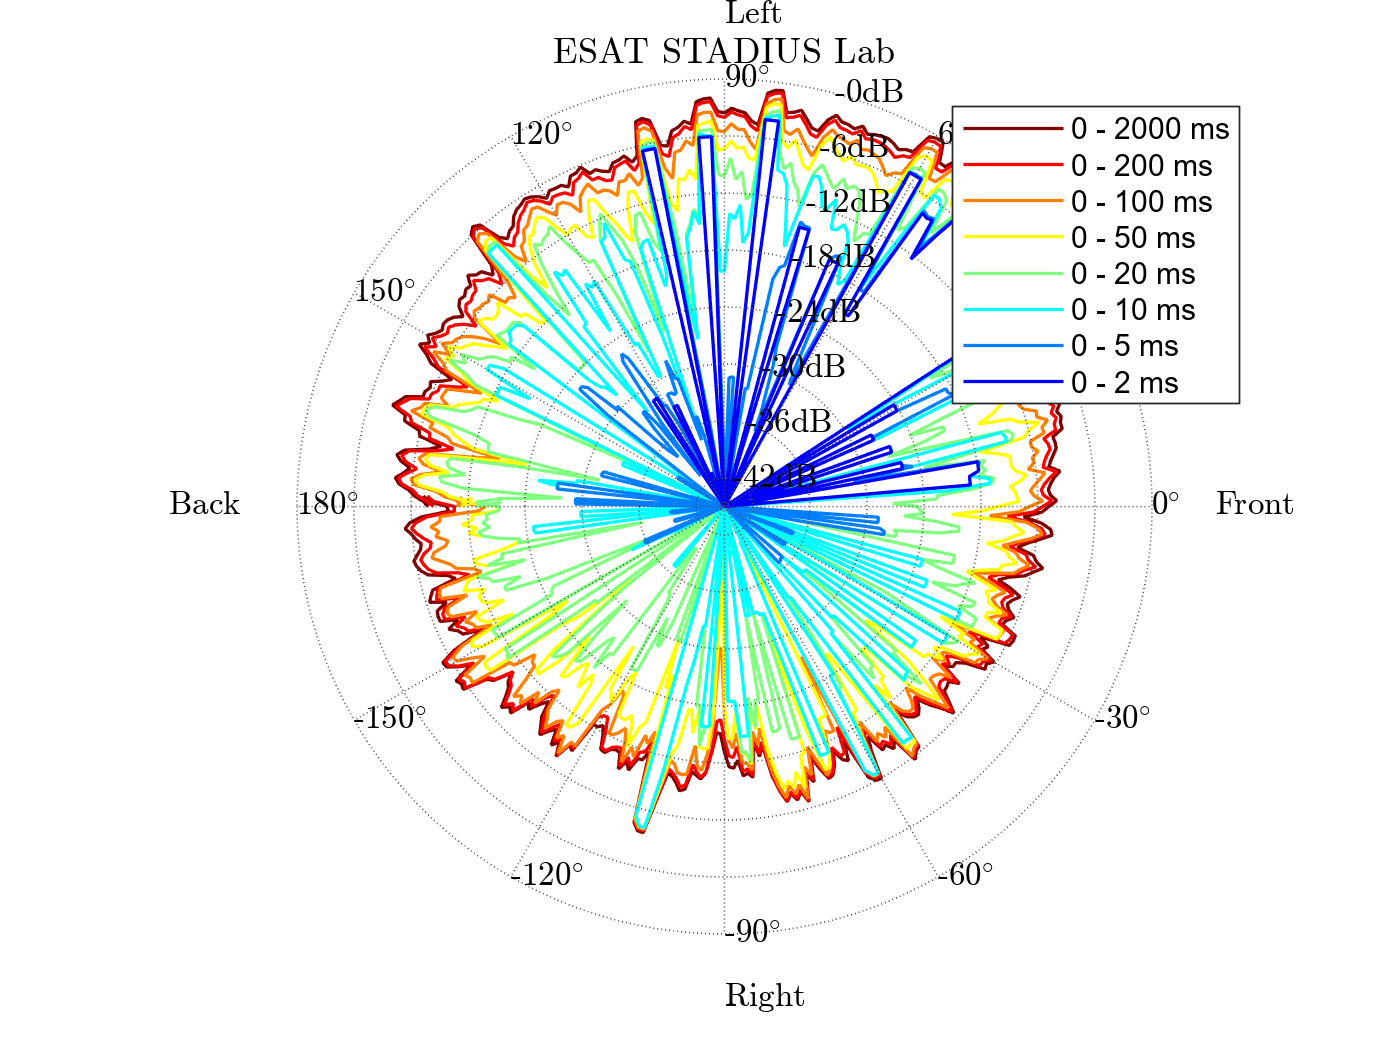

Ended spatio-temporal visualization in 0.30602 seconds.


ans = -83

% Original second measurement
spatioTemporalVisualization(P_original, DOA_original, v)

Started spatio-temporal visualization.


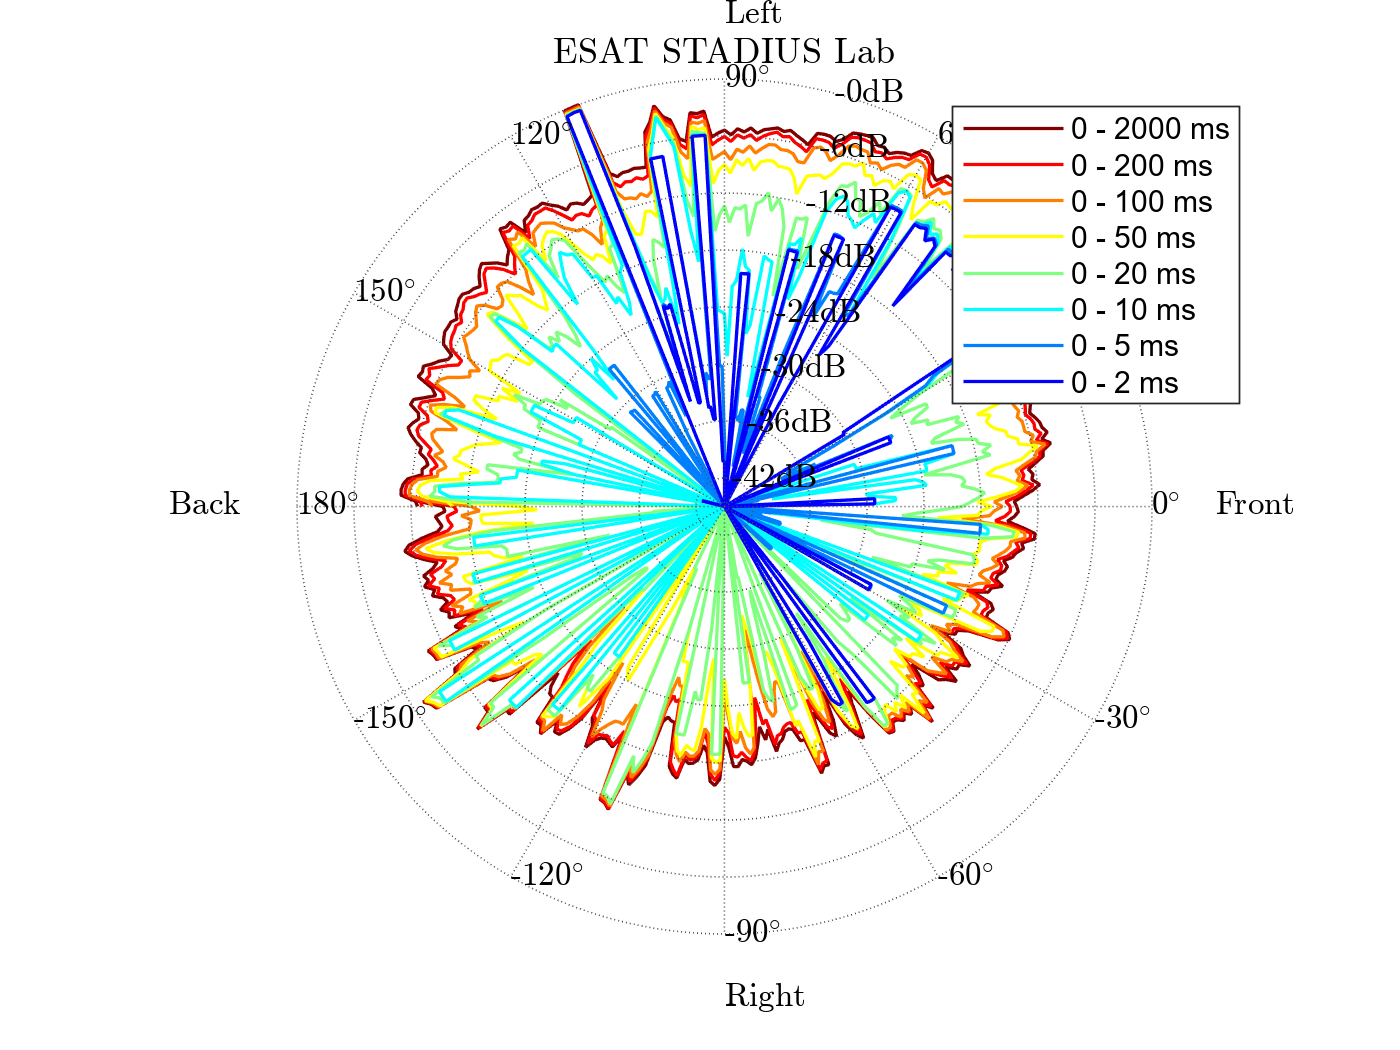

Ended spatio-temporal visualization in 0.29775 seconds.


ans = -111

% Third measurement
spatioTemporalVisualization(P_third, DOA_third, v)

Started spatio-temporal visualization.


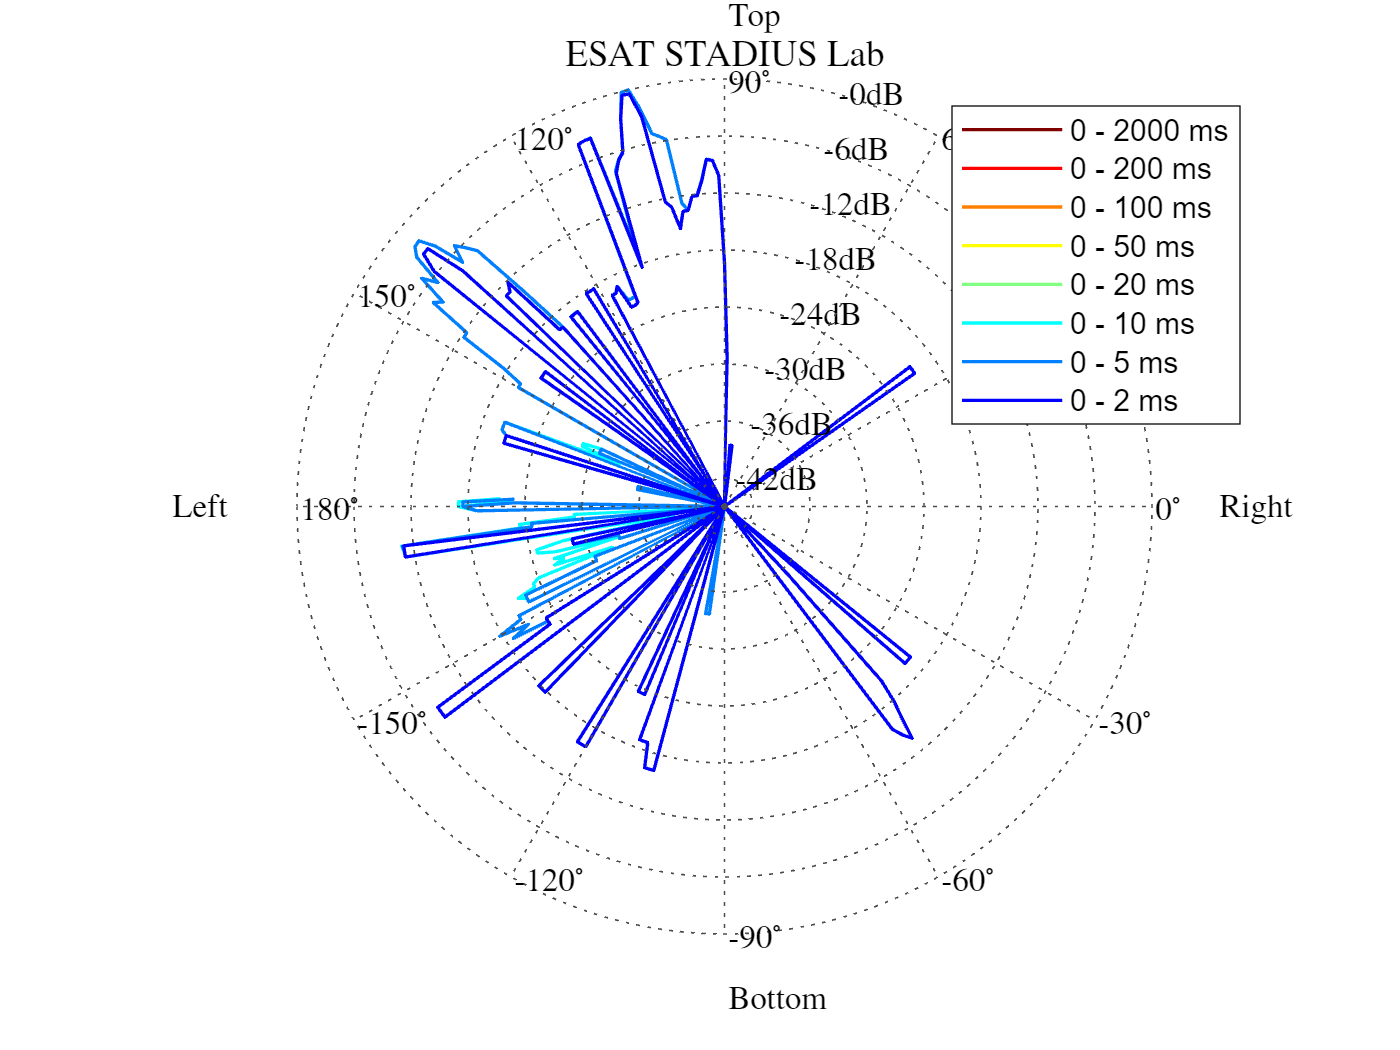

Ended spatio-temporal visualization in 0.33226 seconds.


ans = -105

v.plane = 'transverse';
spatioTemporalVisualization(P_inter, DOA_inter, v)

Started spatio-temporal visualization.


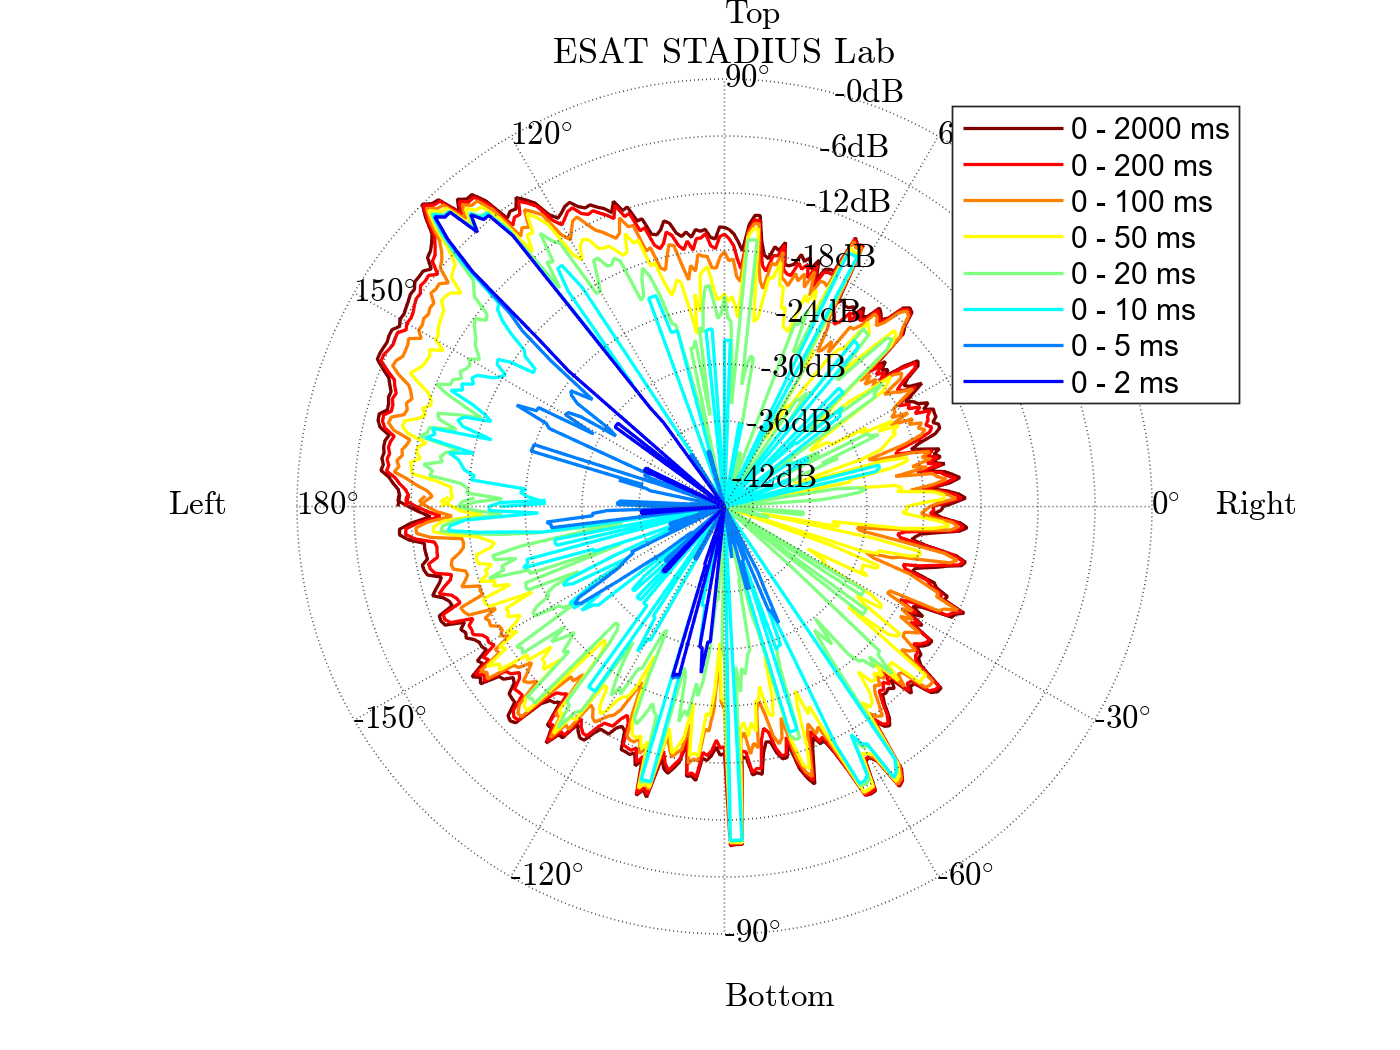

Ended spatio-temporal visualization in 0.31785 seconds.


ans = -136

spatioTemporalVisualization(P_original, DOA_original, v)

Started spatio-temporal visualization.


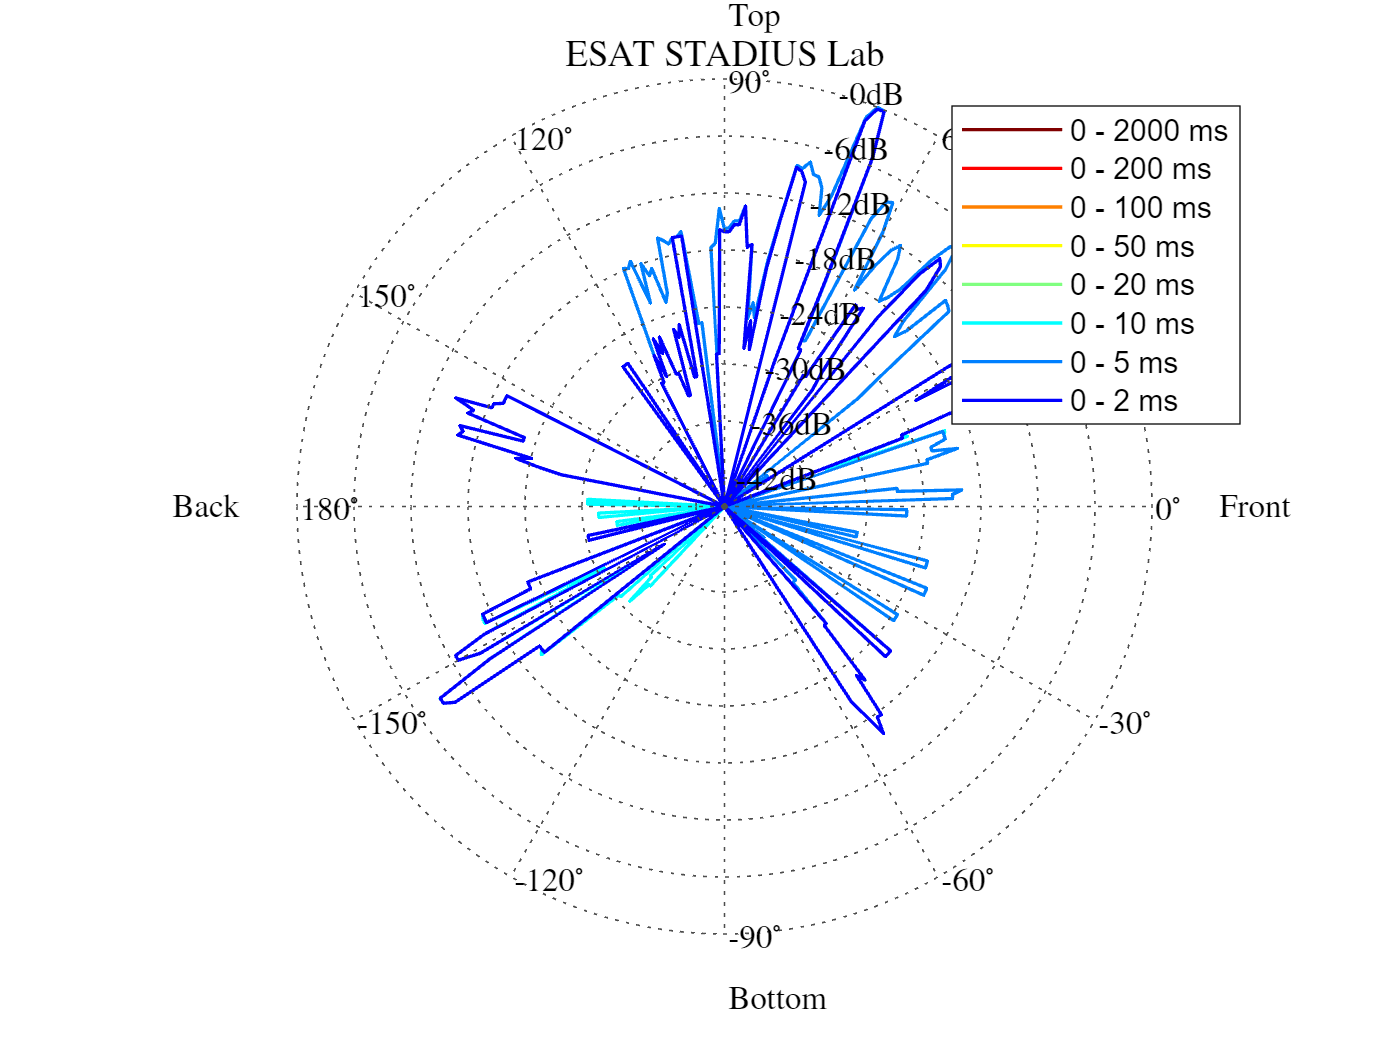

Ended spatio-temporal visualization in 0.29024 seconds.


ans = -69

v.plane = 'median';
spatioTemporalVisualization(P_inter, DOA_inter, v)

Started spatio-temporal visualization.


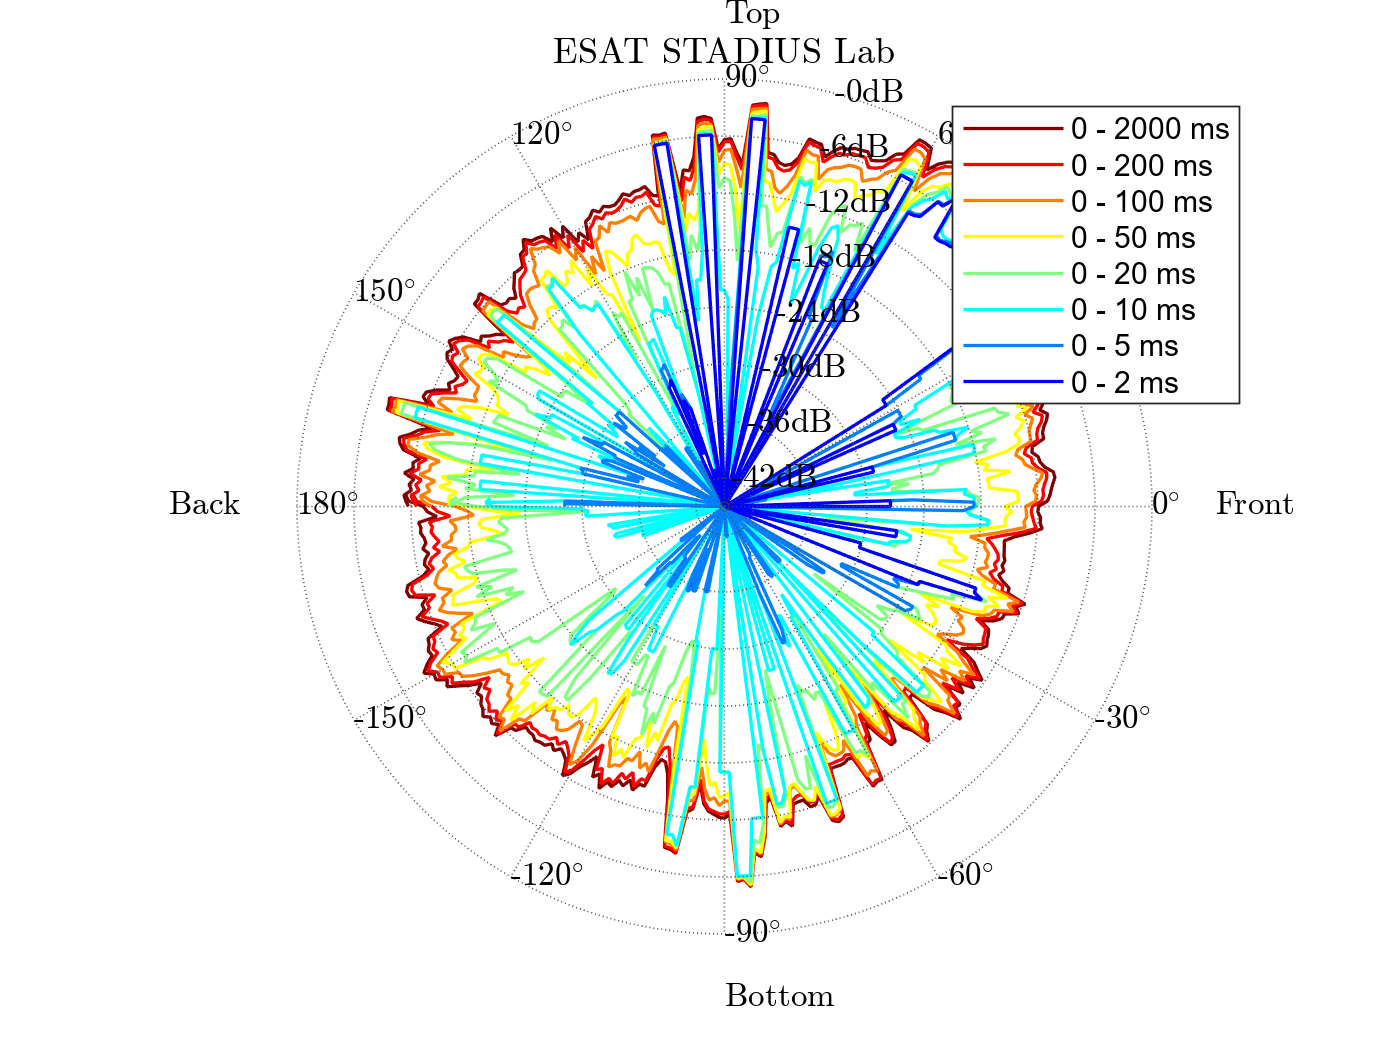

Ended spatio-temporal visualization in 0.32034 seconds.


ans = -85

spatioTemporalVisualization(P_original, DOA_original, v)